%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% EXERCISE 1

syms x y r

fx = -r*x - y + x*y^2

$$fx = x\,y^{2}-y-r\,x$$

fy = x + r*y + y^3

$$fy = y^{3}+r\,y+x$$


% CALCULATE THE FIXED POINTS
disp('Fixed Points as a function of r:')

Fixed Points as a function of r:


[fp_x, fp_y] = solve([fx; fy], [x; y]);
fixPts = [fp_x, fp_y]';
fixPts = fixPts(:, 1:3)

$$fixPts = \left(\begin{array}{ccc} 0 & \bar{{\left(r^{2}-1\right)}^{3/4}}+\bar{r}\,\bar{{\left(r^{2}-1\right)}^{1/4}} & -\bar{{\left(r^{2}-1\right)}^{3/4}}-\bar{r}\,\bar{{\left(r^{2}-1\right)}^{1/4}}\\ 0 & -\bar{{\left(r^{2}-1\right)}^{1/4}} & \bar{{\left(r^{2}-1\right)}^{1/4}} \end{array}\right)$$


disp('As it can be seen in the Fixed Points, we have two bifurcation points at r=-1 and r=1. Thus, we will have five regions, shown below:')

As it can be seen in the Fixed Points, we have two bifurcation points at r=-1 and r=1. Thus, we will have five regions, shown below:


ZONE 1: For r<-1

disp('ZONE 1: r<-1')

ZONE 1: r<-1



% we choose a value r<-1 -> r=-2
fx1 = subs(fx, r, -2);
fy1 = subs(fy, r, -2);

% setting the matlab function for our system
f_lmb1 = @(t,z) [2*z(1) - z(2) + z(1)*z(2)^2;z(1) - 2*z(2) + z(2)^3];

% Computing Fixed points for Zone 1, r=0
fixPts1 = double(subs(fixPts, r, -2))

fixPts1 =          0   -0.3526    0.3526
         0   -1.3161    1.3161



% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts1, 2));
eigenvalues = zeros(size(fixPts1, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts1, 2));

for k = 1:size(fixPts1, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx1, fy1], [x, y]), {x, y}, {fixPts1(1, k), fixPts1(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts1(1,:), fixPts1(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx1 == 0, x);
ycline_y = solve(fy1 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx1, [-1 5 -2 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy1, [-1 5 -2 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-2, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx1, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy1, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 30;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 2, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y1);

basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y2);

basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 1, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[1 3];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb1,tspam, y0);

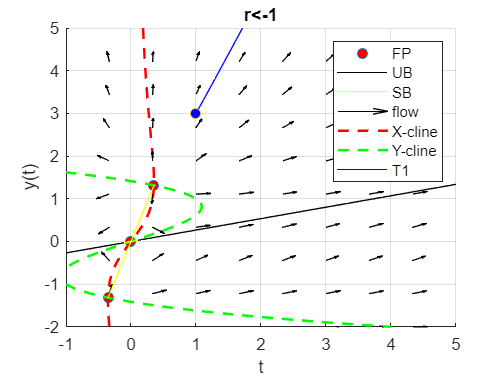

traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -2 5]);
xlabel('t');ylabel('y(t)');grid on; title('r<-1')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('Two unstbale nodes and a saddle in the middle.')

Two unstbale nodes and a saddle in the middle.


ZONE 2: For r=-1

disp('ZONE 2: r=-1')

ZONE 2: r=-1



% we choose a value r=-1
fx2 = subs(fx, r, -1);
fy2 = subs(fy, r, -1);

% setting the matlab function for our system
f_lmb2 = @(t,z) [z(1) - z(2) + z(1)*z(2)^2;z(1) - z(2) + z(2)^3];

% Computing Fixed points for Zone 1, r=0
fixPts2 = double(subs(fixPts, r, -1));
fixPts2 = fixPts2(:,1)

fixPts2 =      0
     0



% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts2, 2));
eigenvalues = zeros(size(fixPts2, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts2, 2));

for k = 1:size(fixPts2, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx2, fy2], [x, y]), {x, y}, {fixPts2(1, k), fixPts2(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts2(1,:), fixPts2(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx2 == 0, x);
ycline_y = solve(fy2 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx2, [-1 5 -2 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy2, [-1 5 -2 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-2, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx2, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy2, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[-0.1 0.1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb2,tspam, y0);

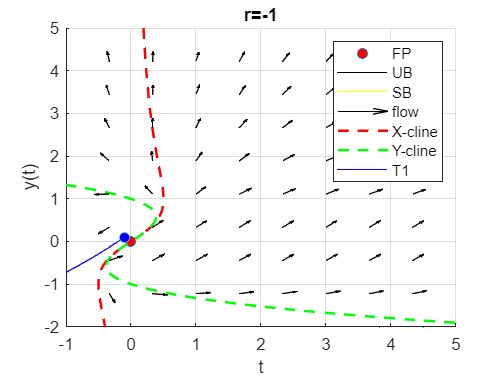

traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -2 5]);
xlabel('t');ylabel('y(t)');grid on; title('r=-1')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('Unstable Spiral?')

Unstable Spiral?


ZONE 3: For -1<r<1

disp('ZONE 3: -1<r<1')

% we choose a value -1<r<1 -> r=0
fx3 = subs(fx, r, 0);
fy3 = subs(fy, r, 0);

% setting the matlab function for our system
f_lmb3 = @(t,z) [- z(2) + z(1)*z(2)^2;z(1) + z(2)^3];

% Computing Fixed points for Zone 1, r=0
fixPts3 = subs(fixPts, r, 0);
fixPts3 = fixPts3(:,1)

% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts3, 2)+ ...
    );
eigenvalues = zeros(size(fixPts3, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts3, 2));

for k = 1:size(fixPts3, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx3, fy3], [x, y]), {x, y}, {fixPts3(1, k), fixPts3(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

h1 = figure;
hold on;
grid on;
fpts = plot(fixPts3(1,:), fixPts3(2,:), 'o', 'MarkerFaceColor', 'r');


% COMPUTE THE NULLCLINES
xcline_x = solve(fx3 == 0, x);
ycline_y = solve(fy3 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx3, [-2 5 -2 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy3, [-2 5 -2 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-2, 5, N);
ylin = linspace(-2, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx3, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy3, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');
axis([-2 5 -2 5]);

% REPRESENT TRAJECTORIES
t0 = 0.5; tf = 50;
tspam = [t0,tf];

% Trajectory 1
y0 =[0.1 0.1];
[ts,ys] = ode45(f_lmb3,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Trajectory 1
y0 =[1 3];
[ts,ys] = ode45(f_lmb3,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');


% SETTING GRAPH PARAMS
xlabel('t');ylabel('y(t)');grid on; title('-1<r<1')
%legend([flow nullX nullY],{'flow', 'X-cline', 'Y-cline'},'Location', 'NorthEast')
hold off

disp('Center or Unstable Spiral?')


ZONE 4: For r=1

disp('ZONE 4: r=1')

% we choose a value r=1
fx4 = subs(fx, r, 1);
fy4 = subs(fy, r, 1);

% setting the matlab function for our system
f_lmb4 = @(t,z) [- z(1) - z(2) + z(1)*z(2)^2;z(1) + z(2) + z(2)^3];

% Computing Fixed points for Zone 1, r=0
fixPts4 = double(subs(fixPts, r, 1));
fixPts4 = fixPts4(:,1)


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts2, 2));
eigenvalues = zeros(size(fixPts2, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts2, 2));

for k = 1:size(fixPts4, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx4, fy4], [x, y]), {x, y}, {fixPts4(1, k), fixPts4(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts4(1,:), fixPts4(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx4 == 0, x);
ycline_y = solve(fy4 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx4, [-1 5 -2 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy4, [-1 5 -2 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-2, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx2, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy2, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[-0.1 0.1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb4,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -2 5]);
xlabel('t');ylabel('y(t)');grid on; title('r=-1')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off

disp('Unstable Spiral?')

ZONE 5: For r>1

disp('ZONE 5: r>1')

% we choose a value r>1 -> r=2
fx5 = subs(fx, r, 2);
fy5 = subs(fy, r, 2);

% setting the matlab function for our system
f_lmb5 = @(t,z) [- 2*z(1) - z(2) + z(1)*z(2)^2;z(1) + 2*z(2) + z(2)^3];

% Computing Fixed points
fixPts5 = double(subs(fixPts, r, 2))

% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts5, 2));
eigenvalues = zeros(size(fixPts5, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts5, 2));

for k = 1:size(fixPts5, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx5, fy5], [x, y]), {x, y}, {fixPts5(1, k), fixPts5(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts5(1,:), fixPts5(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx5 == 0, x);
ycline_y = solve(fy5 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx5, [-5 5 -2 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy5, [-1 5 -2 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-5, 5, N);
ylin = linspace(-2, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx5, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy5, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 30;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 2, 1)*eps)+fixPts5(:,1));
[ts,ys] = ode45(f_lmb5,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts5(:,1));
[ts,ys] = ode45(f_lmb5,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 1, 1)*eps)+fixPts5(:,1));
[ts,ys] = ode45(f_lmb5,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts5(:,1));
[ts,ys] = ode45(f_lmb5,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[1 3];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb5,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-5 5 -2 5]);
xlabel('t');ylabel('y(t)');grid on; title('r<-1')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off

disp('Two unstbale nodes and a saddle in the middle.')
